## Netwon Interpolation

In this livescript, you will learn how

- To use Netwon interpolation approximate functions

For a set of datapoints 


$$(x_{0},f(x_{0})),\ldots,(x_{k},f(x_{k}))$$


The Newton interpolating polynomial is defined as


$$f_{n}(x)=\sum^{k}_{i=0}{b_{i}N_{i}(x)}$$


where $N_{i}}(x)$ is defined as the product


$$N_{i}(x)=\prod^{i-1}_{\ell=0}{(x-x_{\ell})}=(x-x_{0})\cdots(x-x_{i-1})$$


For the rest of this livescript, we'll consider approximating the function


$$f(x)=|\text{sin}(x^{2})|$$


at the sampling points 


$$x=\{-1,-1/3,1/3,1\}$$


x = linspace(-1,1,4)

x =    -1.0000   -0.3333    0.3333    1.0000


f = abs(sin(x.^2))

f =     0.8415    0.1109    0.1109    0.8415


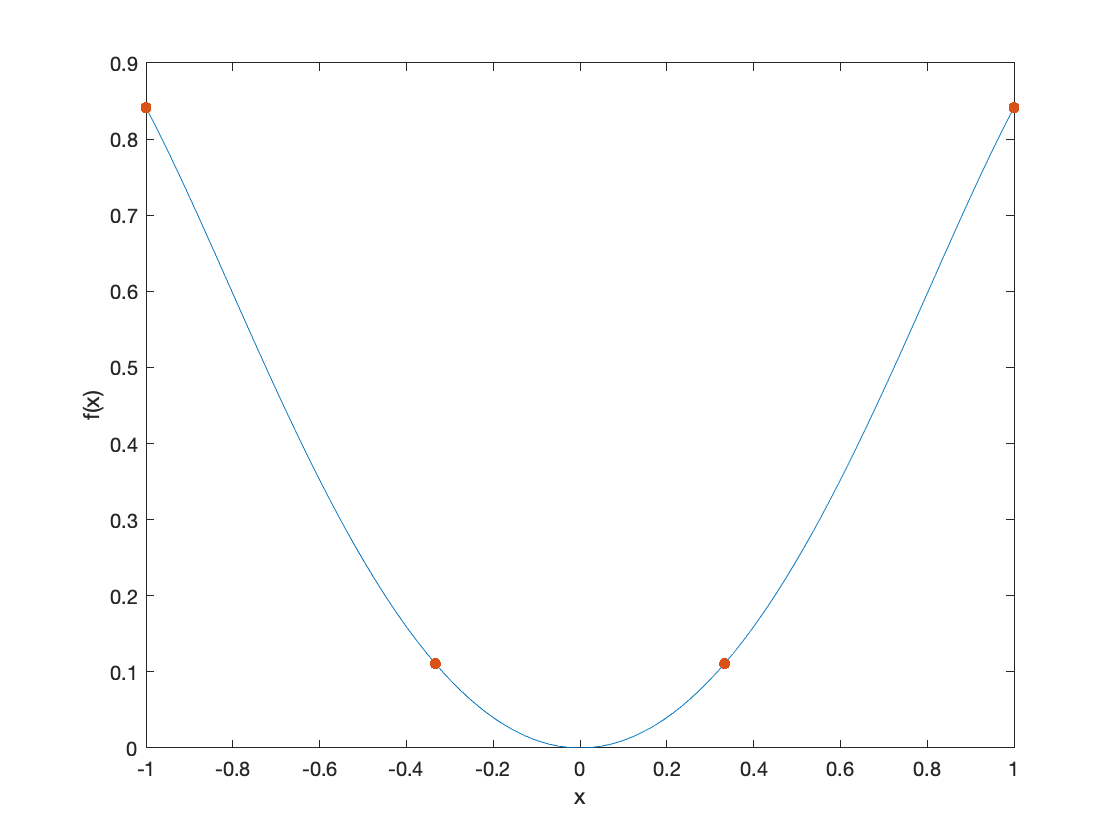


figure
plot(linspace(-1,1,100),abs(sin(linspace(-1,1,100).^2)));
hold on
plot(x,f,'.','MarkerSize',15)
xlabel('x')
ylabel('f(x)')
hold off

### Newton basis polynomials

So let's write a piece of code that computes each $N_{i}}(x)$  at some point $x$.

The inputs of this function will therefore need to be

- The $x$ coordinate.

- The order $i$.

- The interpolation points $x_{\ell}$.

Since there are a known number of computations to be made, we can use a for loop. The idea behind using a loop here is that initially, we set 


$$N_{i,\text{Step 0}}=(x-x_{0})$$


Then going into the loop we multiply out initial condition by $(x-x_{1})$, giving


$$N_{i,\text{Step 1}}=(x-x_{0})(x-x_{1})$$


For the next iteration, we multiply by $(x-x_{2})$, which gives


$$N_{i,\text{Step 2}}=(x-x_{0})(x-x_{1})(x-x_{2})$$


Repeating this process until we reach $(x-x_{i-1})$ would therefore give us the desired result.

Here we have a piece of code that does this for $N_{2}$ at $x=1$, which is sampled at the points $\{1,2,3,4,5\}$.

x = 1;
i = 2;
xpoints = [1,2,3,4,5];
Ni = 1;

for l=1:i
    Ni = Ni*(x-xpoints(l));
end

Ni

Ni = 0

(a)        Convert this piece of code into a function.

### Divided Differences

As for the divided differences $b_{i}$, our inputs will need to be 

- The order $i$.

- The interpolation points $x_{\ell}$ and $y_{\ell}$.

For the coefficients $b_{i}$, the $n^{\text{th}}$ divided difference is given by


$$f[x_{n},\ldots,x_{0}]=\frac{f[x_{n},x_{n-1},\ldots,x_{1}]-f[x_{n-1},x_{n-2},\ldots,x_{0}]}{x_{n}-x_{0}}$$


which we may represent graphically by

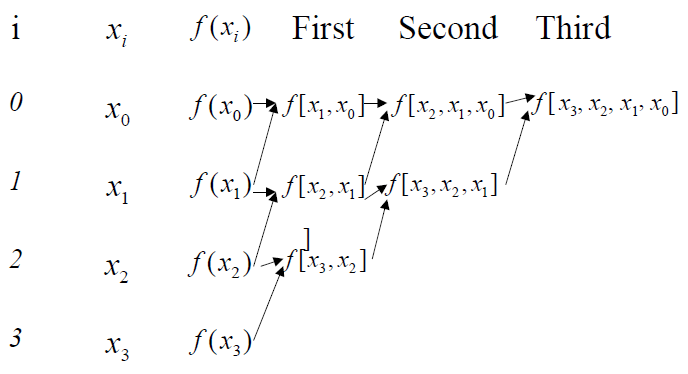

What this is saying is that the $3^{\text{rd}}$ divided difference relies on two $2^{\text{nd}}$ divided difference, which itself relies on three $1^{\text{st}}$ divided differences. 

This recursive definition means that we need to construct our $n^{\text{th}}$ divided difference from the $1^{\text{st}}$ divided difference upwards.

(b)        Determine the $1^{\text{st}}$, $2^{\text{nd}}$, $3^{\text{rd}}$, and $4^{\text{th}}$ divided differences of Eq. (1).

So let's then look at constructing the $1^{\text{st}}$ divided difference using MATLAB. Since we know our end point, we'll use a for loop, then a piece of code that determines the $1^{\text{st}}$ divided differences 


$$f[x_{j},x_{j+1}]=\frac{f(x_{j})-f(x_{j+1})}{x_{j}-x_{j+1}}$$


is

xpoints = linspace(-1,1,4);
ypoints = abs(sin(xpoints.^2));

f0 = ypoints;
f1 = zeros(1,length(f0)-1);

for j=1:length(f0)-1
    f1(j) = (f0(j)-f0(j+1))/(xpoints(j)-xpoints(j+1));
end

f1

(c)        Run the piece of code and check that the code produces the same result.

(d)        Modify the code to construct the second divided differences.

So wrapping the piece of code in a second for loop to determine the $(i+1)^{\text{st}}$ divided difference from the $i^{\text{th}}$ divided difference, we have 

xpoints = linspace(-1,1,4);
ypoints = abs(sin(xpoints.^2));

f1 = zeros(length(xpoints),length(xpoints));
f1(1,:) = ypoints;

for i=1:length(xpoints)-1
    
    for j=1:length(f1)-i
        f1(i+1,j) = (f1(i,j)-f1(i,j+1))/(xpoints(j)-xpoints(j+i));
    end
    
end
f1
disp(f1(end,1))

(e)        Run the piece of code and see if it matches the your result in (a).

(f)         Convert this piece of code into a function.

And so, the Newton interpolating polynomial is given by

xpoints = linspace(-1,1,4);
ypoints = abs(sin(xpoints.^2));

x = linspace(-1,1,100);

f=0;

for i = 0:length(xpoints)-1
    
    f = f+divdiff(xpoints(1:i+1),ypoints(1:i+1)).*newton_N(x,i,xpoints);
    i
end

a = polyfit(xpoints,ypoints,length(xpoints)-1);
fit = polyval(a,x);

plot(xpoints,ypoints,'.','MarkerSize',15)
hold on
plot(x,fit,'x-')
plot(x,f)
hold off
plot(x,abs(fit-f))

For convenience, the Newton basis polynomials are determined using the function $\texttt{newton\_N}$ and the divided differences in the function $\texttt{divdiff}$.